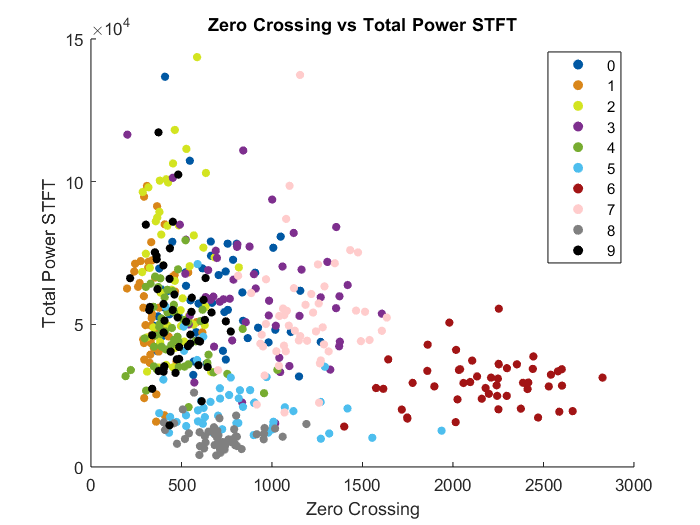

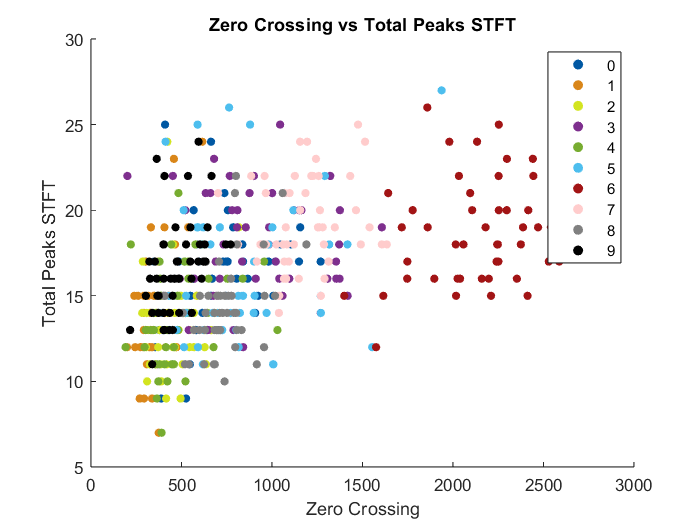

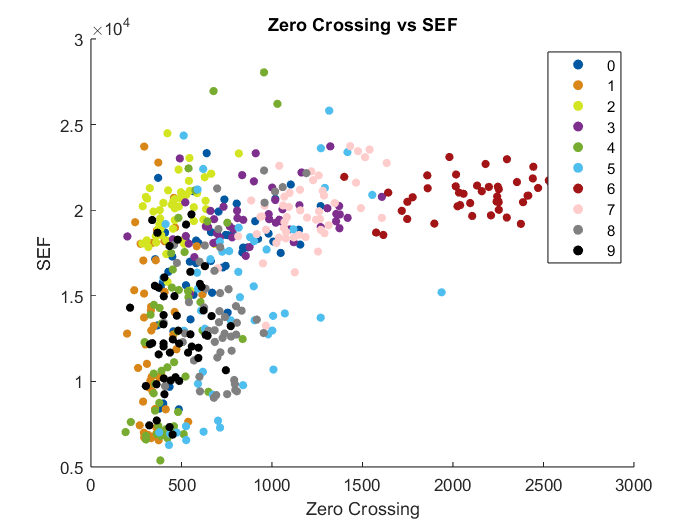

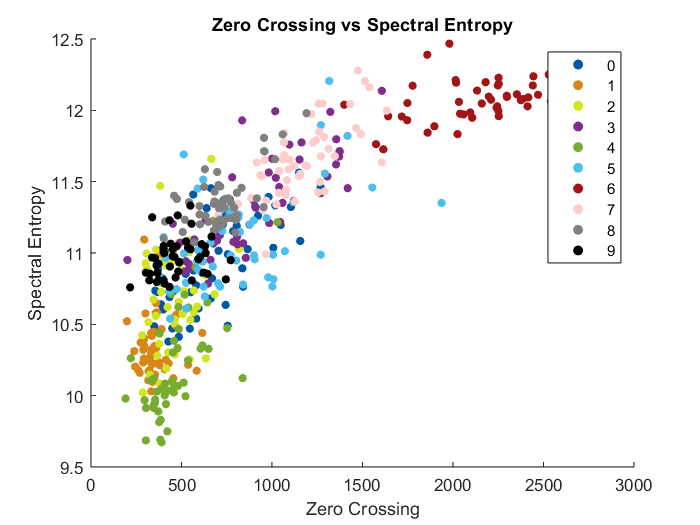

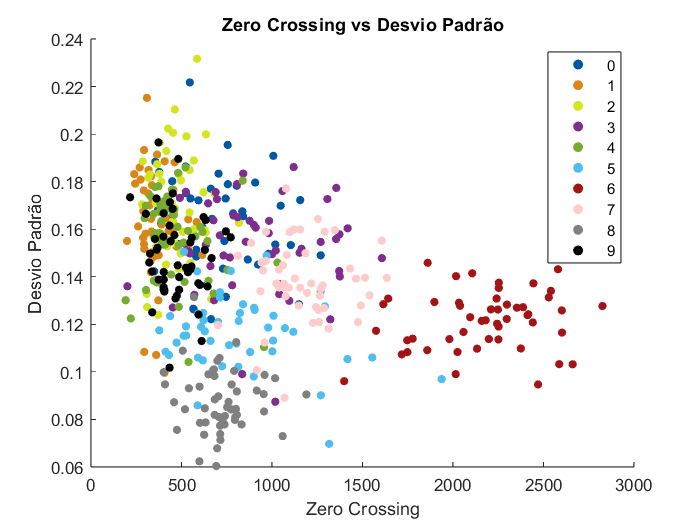

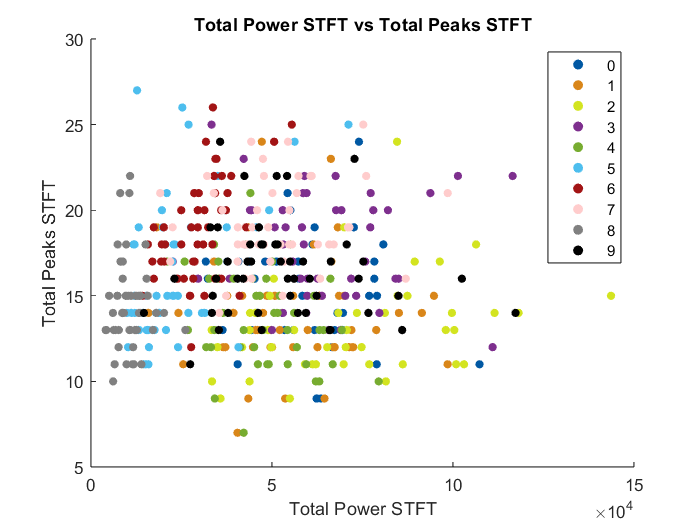

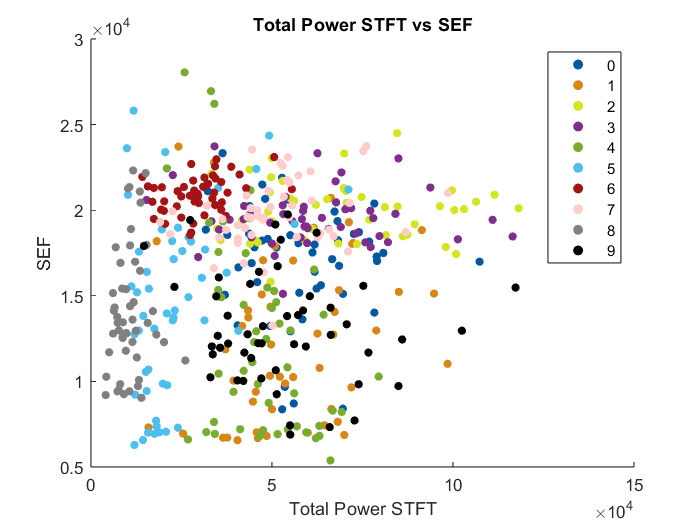

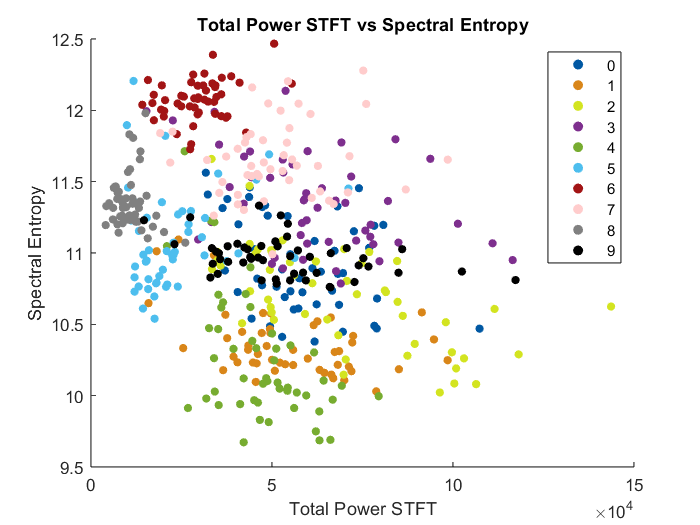

clc
close all
folder = 'C:\Users\Luis Vaz\Documents\Universidade\2Ano\2Semestre\Analise e Transformacao de Dados\Projeto\soerenab AudioMNIST master data-23';
audio_files = dir(fullfile(folder, '*.wav'));
num_files = sum(~[audio_files.isdir]);
Digits = [0, 1, 2, 3, 4, 5, 6, 7, 8, 9];
n = 0;
j = 1;
desired_duration = 0.60; 
digitos = zeros(1,500);

%******************** Variável Gráfico
% Mapa de cores para distinção entre os dígitos
custom_colors = [
    0 0.347 0.641;  % Azul
    0.85 0.525 0.098;  % Vermelho
    0.829 0.894 0.125;  % Amarelo
    0.494 0.184 0.556;  % Roxo
    0.466 0.674 0.188;  % Verde
    0.301 0.745 0.933;  % Azul claro
    0.635 0.078 0.084;  % Castanho
    1 0.8 0.8;  % Rosa
    0.5 0.5 0.5;  % Cinza
    0 0 0];  % Preto
    
%******************** Variáveis Meta 1
% Armazenar características para cada um dos valores
energy = zeros(1, num_files);
max_amp = zeros(1,num_files);
min_amp = zeros(1,num_files);
mean_amp = zeros(1, num_files);
std_dev = zeros(1, num_files);

%Armazear numa matriz (num_files por num_windows)
store_energy_variations = zeros(1,num_files);

%Armazenar as medias dos valores por digito
energy_digit = zeros(1,10);
maxA_digit = zeros(1,10);
minA_digit = zeros(1,10);
meanA_digit = zeros(1,10);
stdDev_digit = zeros(1,10);

%Inicialização dos contadores
energyCounter = 0;
maxAmplitudeCounter = 0;
minAmplitudeCounter = 0;
meanAmplitudeCounter = 0;
stdDevCounter = 0;

%******************** Variáveis Meta 2
% Inicializar arrays para armazenar os máximos espectrais
max_freq_esp = zeros(1, num_files);
max_amp_esp = zeros(1, num_files);
% Inicializar arrays para armazenar as médias espectrais
mean_amp_esp = zeros(1, num_files);
% Inicializar arrays para armazenar o centro de gravidade espectral
spectral_entropy= zeros(1, num_files);
% Inicializar arrays para armazenar o Spectral Edge Frequency (SEF)
SEF = zeros(1, num_files);

%Matrix para armazenar a informação(50 x length(y))
fft_matrix = [];
indice = 0;

%******************** Variáveis Meta 3
%Sacar array de maximos por janela para cada amostra
window_names = {'Default', 'Hamming', 'Blackman', 'Kaiser'};

% Inicialização de array para guardar os valores de potencia comulativa
max_s = zeros(1,500);
total_power = zeros(1, 500);
total_power_stft = zeros(1,500);
zero_crossing = zeros(1,500);
total_mean_power_stft = zeros (1,500);
total_peaks_stft = zeros (1,500);
total_entropy_stft = zeros(1,500);

for repeticao = 1:4
    n = 0; %Controla o nº do ficheiro
    j = 1; %Controla o nº do digito
    
    %Matrix para armazenar a informação(50 x length(y))
    fft_matrix = []; 
    indice = 0; %Controla a posição na matrix
    subplot_pos = 1; %Contola a posição para o subplot
    figure;
    while n < num_files
        n = n+1;
        indice = indice + 1;
        digitos(n) = Digits(j);
        
        filename = fullfile(audio_files(n).folder, audio_files(n).name);
        [y, Fs] = audioread(filename);
        
        Tframe = 0.016; % largura da janela de análise em s
        Toverlap = 0.032; % sobreposiçao das janelas em s
        Nframe = 512;  % número de amostras na janela
        Noverlap = 128;  % número de amostras sobrepostas na janela
        
        % Estratégia 1: Remover o "silêncio" inicial dos sinais
        y = remove_silence(y);
    
        % Estratégia 2: Normalizar a amplitude
        y = normalize_amplitude(y);
    
        % Estratégia 3: Adicionar (ou retirar) silêncio no fim dos ficheiros
        y = adjust_duration(y, Fs, desired_duration);
        
        % Calcular total time e criar vetor de tempo
        total_time = length(y) / Fs;
        t = linspace(0, total_time, length(y));

        %Vamos Calcular features
        energy_total = sum(y.^2); %Energia Total
        max_amplitude = max(abs(y)); % Amplitude Máxima
        min_amplitude = min(abs(y)); % Amplitude Mínima
        mean_amplitude = mean(abs(y)); % Amplitude Média
        std_deviation = std(abs(y)); % Desvio Padrão

        %Atualizar contadores para as médias
        energyCounter = energyCounter + energy_total ;
        maxAmplitudeCounter = maxAmplitudeCounter + max_amplitude;
        minAmplitudeCounter = minAmplitudeCounter + min_amplitude;
        meanAmplitudeCounter = meanAmplitudeCounter + mean_amplitude ;
        stdDevCounter = stdDevCounter + std_deviation;

        %Adicionar valores de cada ficheiro audio ao array que contem os 500
        energy(n) = energy_total;
        max_amp(n) = max_amplitude;
        min_amp(n) = min_amplitude;
        mean_amp(n) = mean_amplitude;
        std_dev(n) = std_deviation;
            
        %Aplicar as janelas ao sinal em cada repetição 
        if(repeticao == 2)
            y = y .* hamming(length(y)); 
        end
             
        if(repeticao == 3)
            y = y .* blackman(length(y));
        end
             
        if(repeticao == 4)
            y =  y.* kaiser(length(y)); 
        end
             
        %Aplicar a Transformada de Fourier aos valores da amplitude de y, normalizando pelo nº de amostras
        Y = fft(y)/length(y);
        SizeY = length(Y);
        %Ficar só com as frequencias positivas
        N = round(length(Y)/2);
        
        %Verificar se a matrix está vazia e se estiver inicializa-la com o tamanho correto
        if isempty(fft_matrix)
            fft_matrix = zeros(50, N);
        end
        %Espaçameto entre as frequencias
        frequencies = (0:N-1)  * Fs/N;
        num_freq = length(frequencies);
       
        %Inserir na matriz os valores obtidos pra cada frequencia
        fft_matrix(indice,:) = abs(Y(1:N));
       
        % Encontrar os máximos espectrais
        [pks, locs] = findpeaks(abs(Y), 'MinPeakDistance', 100); % Encontrar picos com uma distância mínima de 100Hz
        [max_amp_esp(n), idx] = max(pks); % Identificar a amplitude do pico máximo
        max_freq_esp(n) = frequencies(locs(idx)); % Identificar a frequência do pico máximo
        
        % Calcular o espectro de magnitude
        spectral_magnitude = abs(Y(1:N));
        mean_amp_esp(n) = mean(spectral_magnitude(:));
        
        % Normalizar o espectro de magnitude
        normalized_spectrum = spectral_magnitude / sum(spectral_magnitude);
        
        % Calcular a entropia espectral
        spectral_entropy(n) = -sum(normalized_spectrum .* log2(normalized_spectrum + eps)); %eps é um pequeno valor adicionado para evitar o logaritmo de zero.

        % Calcular o Spectral Edge Frequency (SEF)
        cumulative_power = cumsum(spectral_magnitude); % Calcula a energia acumulada
        total_power = sum(spectral_magnitude); % Calcula a energia total
        SEF(n) = frequencies(find(cumulative_power >= 0.9 * total_power, 1)); % Encontra a frequência correspondente a 90% da energia total
     
        if (repeticao == 1)
            
            [s,f,t] = spectrogram(y,Nframe,Noverlap,[],Fs);
            % Get the maximum magnitude for each column (time frame) of the spectrogram matrix
            max_magnitude = max(abs(s), [], 1);
            
            %Calcular potencia total por sample
            y_power = sum(max_magnitude.^2); 
            total_power_stft(n) = y_power;
            
            % Calcular picos máximos
            [~,locs] = findpeaks(max_magnitude);
            num_peaks = length(locs);
            total_peaks_stft(n) = num_peaks;
            % Calcular potência média por janela
            mean_power = y_power / length(max_magnitude);
            total_mean_power_stft(n) = mean_power;
            zero_crossing(n) = zeroCrossingRate(y);
            
        %Aplicar as janelas ao sinal em cada repetição 
        elseif(repeticao == 2)
            y = y .* hamming(length(y));  
        elseif(repeticao == 3)
            y = y .* blackman(length(y));
        %Valor de Beta escolhido = 5
        elseif(repeticao == 4)
            y =  y.* kaiser(length(y),5); 
        end
        
        %Mudança de digito
        if (mod(n,50)==0)
            %Adicionar valores medios aos arrays para as medias dos digitos 
            energy_digit(j)= energyCounter/50;
            maxA_digit(j) = maxAmplitudeCounter/50;
            minA_digit(j) = minAmplitudeCounter/50;
            meanA_digit(j) = meanAmplitudeCounter/50;
            stdDev_digit(j) = stdDevCounter/50;

            %Reset à variavel que armazena
            energyCounter = 0;
            maxAmplitudeCounter = 0;
            minAmplitudeCounter = 0;
            meanAmplitudeCounter = 0;
            stdDevCounter = 0;

            %{       
            %Plot do sinal de áudio
            plot(t, y)
            xlabel('Tempo (segundos)')
            ylabel('Amplitude')
            title(['digito ' num2str(Digits(j))])
            grid on
             %} 

            %Calcular a mediana, e quartis
            median_array = median(fft_matrix);
            first_quantil_array = quantile(fft_matrix, 0.25);
            third_quantil_array = quantile(fft_matrix, 0.75);
            ArraysSize = length(median_array);

%             % Plotting
%             subplot(5,2,subplot_pos);
%             hold on;
%             plot(frequencies, (median_array), 'b', 'LineWidth', 0.5);  % Plot median in blue
%             plot(frequencies, (first_quantil_array), 'r', 'LineWidth', 0.5);  % Plot 25th percentile in red
%             plot(frequencies, (third_quantil_array), 'Color',[0.9, 0.5, 0], 'LineWidth', 0.5);  % Plot 75th percentile in yellow
%             hold off;
% 
%             % Set title and legend
%             xlim([0 8000]);  % Limit x-axis to Nyquist frequency
%             
%             if(repeticao == 1)
%                  title(['Original Window >> Median and Quartiles for digit ' num2str(Digits(j))]);
%             end
%            
%             if(repeticao == 2)
%                  title(['Window Hamming >> Median and Quartiles for digit ' num2str(Digits(j))]);
%             end
%             
%             if(repeticao == 3)
%                  title(['Window Blackman >> Median and Quartiles for digit ' num2str(Digits(j))]);
%             end
%             
%             if(repeticao == 4)
%                  title(['Window Kaiser >> Median and Quartiles for digit ' num2str(Digits(j))]);
%             end
%             
%             legend('Median', 'Q25', 'Q75');
%             grid on;
% 
%             %Limpar a matrix para preparar a proxima iteração
%             fft_matrix = zeros(50, N);
%             
%             %Compute the short-time Fourier
%             subplot(5,2,j);
%             hold on;
%             
%             %Plot the spectrogram
%             spectrogram(y,Nframe,Noverlap,[],Fs,'yaxis')
%             %[s,f,t] = spectrogram(y,Nframe,Noverlap,[],Fs);
%             ylim([0 15]);
%             title(sprintf('Digit: %d - Window: %s', Digits(j), window_names{repeticao}));
%             
%             hold off;
%             grid on;
            j = j + 1; 
            subplot_pos = subplot_pos +1;
            indice = 0;
        end 
        % Calcular características temporais          
        window_size = 0.1; % Tamanho da janela em segundos
        window_samples = round(window_size * Fs); % Número de amostras por janela
        num_windows = floor(length(y) / window_samples); % Número de janelas
        energy_intervals = zeros(1, num_windows); % Energia por intervalos temporais
        for i = 1:num_windows
            start_idx = (i - 1) * window_samples + 1;
            end_idx = min(i * window_samples, length(y));
            
            %Calculo da energia do intervalo
            energy_intervals(i) = sum(y(start_idx:end_idx).^2);
        end   
        store_energy_variations(n, 1:num_windows) = energy_intervals;             
    end
end

% %*********************** Plot Meta 1
% % Plot dos scatter plots
% figure;
% subplot(2,2,1);
% scatter(digitos, energy);
% xlabel('Dígito');
% ylabel('Energia Total');
% title('Energia Total');
% 
% subplot(2,2,2);
% scatter(digitos, mean_amp);
% xlabel('Dígito');
% ylabel('Amplitude Média');
% title('Amplitude Média');
% 
% subplot(2,2,3);
% scatter(digitos, std_dev);
% xlabel('Dígito');
% ylabel('Desvio Padrão');
% title('Desvio Padrão');
% 
% % Plot dos boxplots
% figure;
% subplot(2,2,1);
% boxplot(energy, digitos);
% xlabel('Digito');
% ylabel('Energia Total');
% title('Boxplot da Energia Total');
% 
% subplot(2,2,2);
% boxplot(mean_amp, digitos);
% xlabel('Digito');
% ylabel('Amplitude Média');
% title('Boxplot da Amplitude Média');
% 
% subplot(2,2,3);
% boxplot(std_dev, digitos);
% xlabel('Digito');
% ylabel('Desvio Padrão');
% title('Boxplot do Desvio Padrão');
% 
% % Plot dos scatter plots 2D
% figure;
% subplot(2,2,1);
% colormap('jet');
% scatter(mean_amp, energy, [], digitos, 'filled');
% xlabel('Amplitude Média');
% ylabel('Energia Total');
% title('Scatter Plot em 2D');
% % Mapeamento de cores para os digitos
% unique_digitos = unique(digitos); % Obtém os digitos únicos
% hold on;
% l = cell(1, length(unique_digitos));
% for i = 1:length(unique_digitos)
%     idx = digitos == unique_digitos(i);
%     scatter(mean_amp(idx), energy(idx), [],custom_colors(i, :), 'filled');
%     l{i} = sprintf('%d', unique_digitos(i));
% end
% hold off;
% legend(l);
% 
% subplot(2,2,2);
% colormap('jet');
% scatter(std_dev, energy, [], digitos, 'filled');
% xlabel('Desvio Padrão');
% ylabel('Energa Total');
% title('Scatter Plot em 2D');
% % Mapeamento de cores para os digitos
% unique_digitos = unique(digitos); % Obtém os digitos únicos
% hold on;
% l = cell(1, length(unique_digitos));
% for i = 1:length(unique_digitos)
%     idx = digitos == unique_digitos(i);
%     scatter(std_dev(idx), energy(idx), [],custom_colors(i, :), 'filled');
%     l{i} = sprintf('%d', unique_digitos(i));
% end
% hold off;
% legend(l);
% 
% subplot(2,2,3);
% colormap('jet');
% scatter(mean_amp, std_dev, [], digitos, 'filled');
% xlabel('Amplitude Média');
% ylabel('Desvio Padrão');
% title('Scatter Plot em 2D');
% % Mapeamento de cores para os digitos
% unique_digitos = unique(digitos); % Obtém os digitos únicos
% hold on;
% l = cell(1, length(unique_digitos));
% for i = 1:length(unique_digitos)
%     idx = digitos == unique_digitos(i);
%     scatter(mean_amp(idx), std_dev(idx), [],custom_colors(i, :), 'filled');
%     l{i} = sprintf('%d', unique_digitos(i));
% end
% hold off;
% legend(l);
% 
% 
% % Plot dos scatter plots 3D
% figure;
% 
% scatter3(mean_amp, std_dev, energy, [], digitos, 'filled');
% xlabel('Amplitude Média');
% ylabel('Desvio Padrão');
% zlabel('Energia Total');
% title('Scatter Plot em 3D');
% % Mapeamento de cores para os digitos
% unique_digitos = unique(digitos); % Obtém os digitos únicos
% hold on;
% l = cell(1, length(unique_digitos));
% for i = 1:length(unique_digitos)
%     idx = digitos == unique_digitos(i);
%     scatter3(mean_amp(idx), std_dev(idx), energy(idx), [],custom_colors(i, :), 'filled');
%     l{i} = sprintf('%d', unique_digitos(i));
% end
% hold off;
% legend(l);
% %*********************** Plot Meta 2
% % Plot dos scatter plots dos máximos espectrais
% figure;
% subplot(2,1,1);
% scatter(digitos, max_freq_esp);
% xlabel('Dígito');
% ylabel('Frequência do Pico Máximo (Hz)');
% title('Frequência do Pico Máximo');
% 
% subplot(2,1,2);
% scatter(digitos, max_amp_esp);
% xlabel('Dígito');
% ylabel('Amplitude do Pico Máximo');
% title('Amplitude do Pico Máximo');
% 
% % Plot dos scatter plots dos máximos espectrais
% figure;
% subplot(2,2,1);
% scatter(digitos, max_freq_esp);
% xlabel('Dígito');
% ylabel('Frequência do Pico Máximo (Hz)');
% title('Frequência do Pico Máximo');
% 
% subplot(2,2,2);
% scatter(digitos, max_amp_esp);
% xlabel('Dígito');
% ylabel('Amplitude do Pico Máximo');
% title('Amplitude do Pico Máximo');
% 
% % Plot dos boxplots dos máximos espectrais
% subplot(2,2,3);
% boxplot(max_freq_esp, digitos);
% xlabel('Dígito');
% ylabel('Frequência do Pico Máximo (Hz)');
% title('Boxplot da Frequência do Pico Máximo');
% 
% subplot(2,2,4);
% boxplot(max_amp_esp, digitos);
% xlabel('Dígito');
% ylabel('Amplitude do Pico Máximo');
% title('Boxplot da Amplitude do Pico Máximo');
% 
% % Plot dos resultados das médias espectrais
% figure;
% subplot(2,1,1);
% scatter(digitos, mean_amp_esp);
% xlabel('Dígito');
% ylabel('Média das Amplitudes');
% title('Médias das Amplitudes');
% 
% subplot(2,1,2);
% boxplot(mean_amp_esp, digitos);
% xlabel('Dígito');
% ylabel('Média das Amplitudes');
% title('Médias das Amplitudes');
% 
% % Plot dos resultados de Entropia Espectral
% figure;
% subplot(2,1,1);
% scatter(digitos, spectral_entropy);
% xlabel('Dígito');
% ylabel('Entropia Espectral (Hz)');
% title('Entropia Espectral');
% 
% subplot(2,1,2);
% boxplot(spectral_entropy, digitos);
% xlabel('Dígito');
% ylabel('Entropia Espectral (Hz)');
% title('Entropia Espectral');
% 
% % Plot dos resultados do Spectral Edge Frequency (SEF)
% figure;
% subplot(2,1,1);
% scatter(digitos, SEF);
% xlabel('Dígito');
% ylabel('Spectral Edge Frequency (Hz)');
% title('Spectral Edge Frequency (SEF)');
% 
% subplot(2,1,2);
% boxplot(SEF, digitos);
% xlabel('Dígito');
% ylabel('Spectral Edge Frequency (Hz)');
% title('Spectral Edge Frequency (SEF)');
% 
% % Plot 3D 
% figure;
% scatter3(max_amp_esp, spectral_entropy, SEF, [], digitos, 'filled');
% xlabel('Máximo das Amplitudes');
% ylabel('Entropia Espectral');
% zlabel('Spectral Edge Frequency (Hz)');
% title('Gráfico 3D: Máximo Espectral vs. Entropia Espectral vs. SEF');
% %colormap(custom_colors);
% % Mapeamento de cores para os digitos
% unique_digitos = unique(digitos); % Obtém os digitos únicos
% hold on;
% l = cell(1, length(unique_digitos));
% for i = 1:length(unique_digitos)
%     idx = digitos == unique_digitos(i);
%     scatter3(max_amp_esp(idx), spectral_entropy(idx), SEF(idx), [],custom_colors(i, :), 'filled');
%     l{i} = sprintf('%d', unique_digitos(i));
% end
% hold off;
% legend(l);
% 
% 
% %*********************** Plot Meta 3
% 
% % Plot dos boxplots
% figure;
% subplot(2,1,1);
% boxplot(total_power_stft, digitos);
% xlabel('Digito');
% ylabel('Potencia Total');
% title('Boxplot da Potencia Total');
% 
% subplot(2,1,2);
% scatter(digitos, total_power_stft);
% xlabel('Dígito');
% ylabel('Potencia Total');
% title('Potencia Total');
% 
% % Gráfico de dispersão
% 
% figure
% subplot(2,1,1);
% boxplot(total_peaks_stft, digitos);
% xlabel('Digito');
% ylabel('Número de Picos Máximos');
% title('Boxplot dos Picos Máximos');
% 
% % Gráfico de dispersão
% subplot(2,1,2);
% scatter(digitos, total_peaks_stft);
% xlabel('Dígito');
% ylabel('Número de Picos Máximos');
% title('Picos Máximos');
% 
% figure
% subplot(2,1,1);
% boxplot(total_mean_power_stft, digitos);
% xlabel('Digito');
% ylabel('Potência Média por Janela');
% title('Boxplot da Potência Média por Janela');
% 
% subplot(2,1,2);
% scatter(digitos, total_mean_power_stft);
% xlabel('Dígito');
% ylabel('Potência Média por Janela');
% title('Potência Média por Janela');
% 
% figure
% subplot(2,1,1);
% boxplot(zero_crossing, digitos);
% xlabel('Digito');
% ylabel('Zero Crossing');
% title('Boxplot da Zero Crossing por Janela');
% 
% subplot(2,1,2);
% scatter(digitos, zero_crossing);
% xlabel('Dígito');
% ylabel('Zero Crossing por Janela');
% title('Zero Crossing por Janela');
% 
% % Plot 3D 
% figure;
% scatter3(zero_crossing, total_mean_power_stft, total_power_stft, [], digitos, 'filled');
% xlabel('Zero Crossing');
% ylabel('Potência Média');
% zlabel('Potência Total');
% title('Gráfico 3D: Zero Crossing vs. Potência Média vs. Potência Total');
% 
% % Mapeamento de cores para os digitos
% unique_digitos = unique(digitos); % Obtém os digitos únicos
% hold on;
% l = cell(1, length(unique_digitos));
% for i = 1:length(unique_digitos)
%     idx = digitos == unique_digitos(i);
%     scatter3(zero_crossing(idx), total_mean_power_stft(idx), total_power_stft(idx), [],custom_colors(i, :), 'filled');
%     l{i} = sprintf('%d', unique_digitos(i));
% end
% hold off;
% legend(l);
% 
% % Plot 3D 
% figure;
% scatter3(zero_crossing, total_mean_power_stft, total_peaks_stft, [], digitos, 'filled');
% xlabel('Zero Crossing');
% ylabel('Potência Média');
% zlabel('Picos Máximos');
% title('Gráfico 3D: Zero Crossing vs. Potência Média vs. Picos Máximos');
% 
% % Mapeamento de cores para os digitos
% unique_digitos = unique(digitos); % Obtém os digitos únicos
% hold on;
% l = cell(1, length(unique_digitos));
% for i = 1:length(unique_digitos)
%     idx = digitos == unique_digitos(i);
%     scatter3(zero_crossing(idx), total_mean_power_stft(idx), total_peaks_stft(idx), [],custom_colors(i, :), 'filled');
%     l{i} = sprintf('%d', unique_digitos(i));
% end
% hold off;
% legend(l);

%************************ Gráficos
% Converter os vetores de características em uma matriz
features_matrix = [zero_crossing; total_power_stft; total_peaks_stft; SEF; spectral_entropy; std_dev];

% Definir pares de características
feature_pairs = {
    {'Zero Crossing', 'Total Power STFT'},
    {'Zero Crossing', 'Total Peaks STFT'},
    {'Zero Crossing', 'SEF'},
    {'Zero Crossing', 'Spectral Entropy'},
    {'Zero Crossing', 'Desvio Padrão'},
    {'Total Power STFT', 'Total Peaks STFT'},
    {'Total Power STFT', 'SEF'},
    {'Total Power STFT', 'Spectral Entropy'},
    {'Total Power STFT', 'Desvio Padrão'},
    {'Total Peaks STFT', 'SEF'},
    {'Total Peaks STFT', 'Spectral Entropy'},
    {'Total Peaks STFT', 'Desvio Padrão'},
    {'SEF', 'Spectral Entropy'},
    {'SEF', 'Desvio Padrão'},
    {'Spectral Entropy', 'Desvio Padrão'}
};

% Iterar sobre os pares de características e plotar os gráficos de dispersão
for i = 1:numel(feature_pairs)
    % Selecionar as características atuais
    feat1_name = feature_pairs{i}{1};
    feat2_name = feature_pairs{i}{2};
    
    % Encontrar os índices das características atuais
    feat1_idx = find(strcmp(feat1_name, {'Zero Crossing', 'Total Power STFT', 'Total Peaks STFT', 'SEF', 'Spectral Entropy', 'Desvio Padrão'}));
    feat2_idx = find(strcmp(feat2_name, {'Zero Crossing', 'Total Power STFT', 'Total Peaks STFT', 'SEF', 'Spectral Entropy', 'Desvio Padrão'}));
    
    % Selecionar as características atuais
    feat1 = features_matrix(feat1_idx, :);
    feat2 = features_matrix(feat2_idx, :);
    
    figure;
    unique_digitos = unique(digitos); % Obtém os dígitos únicos
    l = cell(1, length(unique_digitos));
    hold on;
    for j = 1:length(unique_digitos)
        current_digit = unique_digitos(j);
        idx = digitos == current_digit;
        scatter(feat1(idx), feat2(idx), 25, custom_colors(current_digit + 1, :), 'filled');
        l{j} = sprintf('%d', current_digit);
    end
    legend(l);
    hold off;
    
    xlabel(feature_pairs{i}{1});
    ylabel(feature_pairs{i}{2});
    title(sprintf('%s vs %s', feature_pairs{i}{1}, feature_pairs{i}{2}));
end

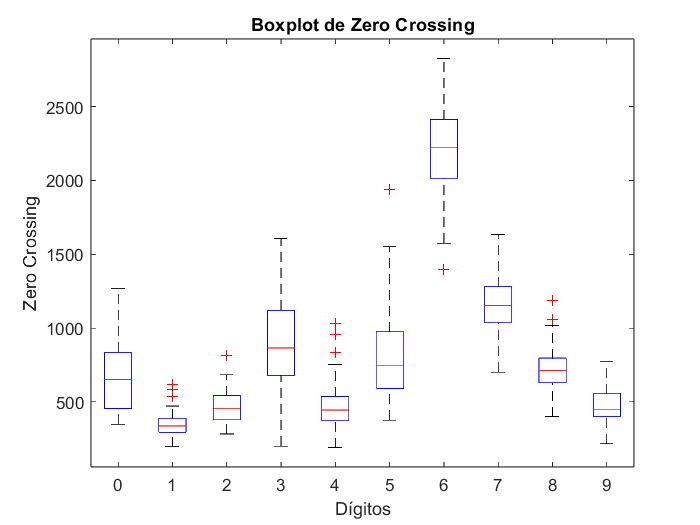

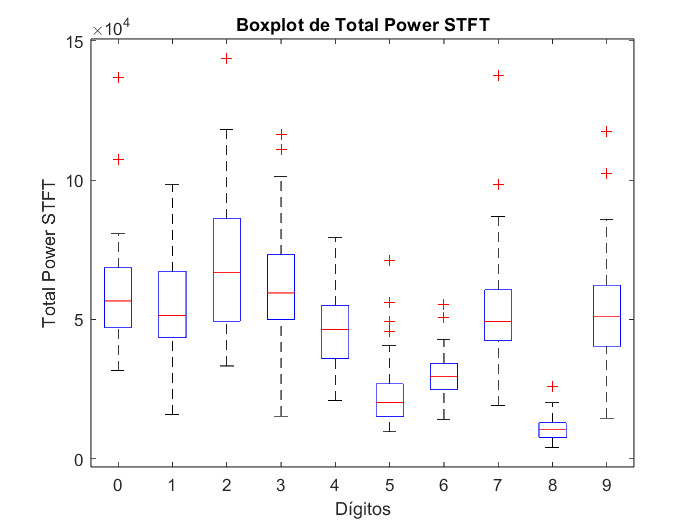

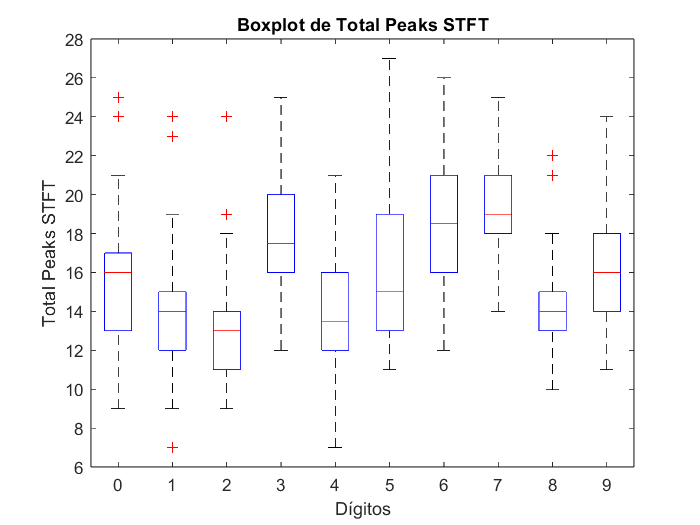

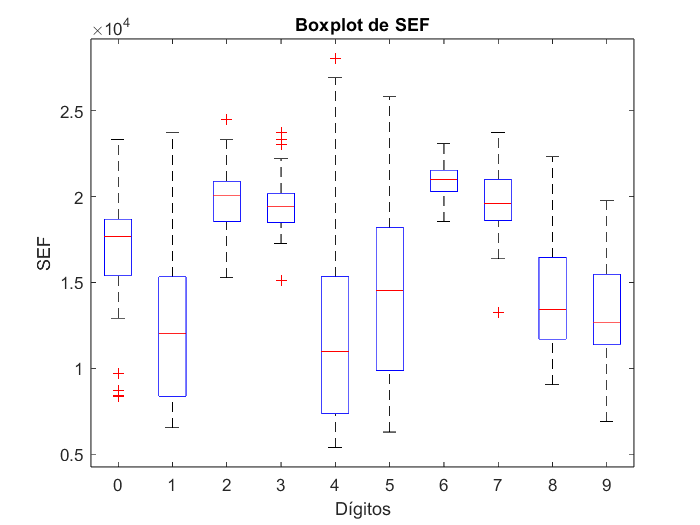

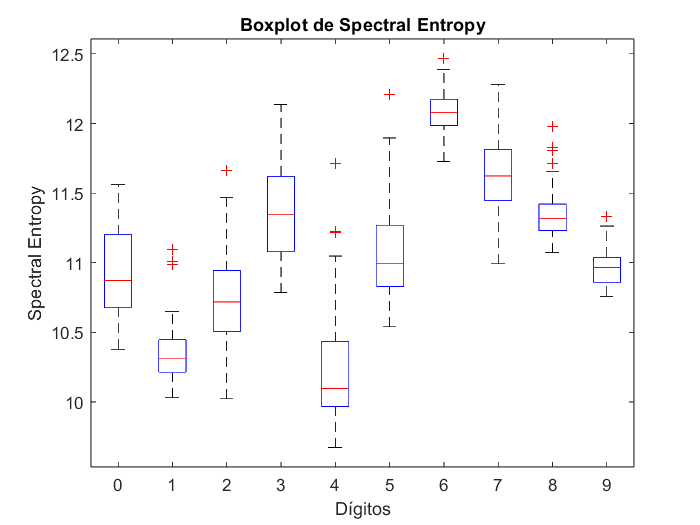

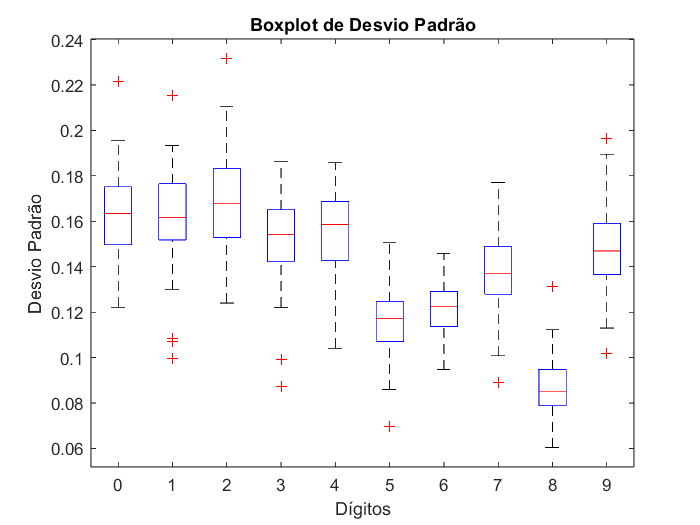


% Definir o número de características para plotagem
num_features = size(features_matrix, 1);

% Iterar sobre todas as características
for i = 1:num_features
    % Selecionar a característica atual
    feature_name = {'Zero Crossing', 'Total Power STFT', 'Total Peaks STFT', 'SEF', 'Spectral Entropy', 'Desvio Padrão'};
    feat = features_matrix(i, :);
    figure;
    boxplot(feat, digitos);
    xlabel('Dígitos');
    ylabel(feature_name{i});
    title(sprintf('Boxplot de %s', feature_name{i}));
end

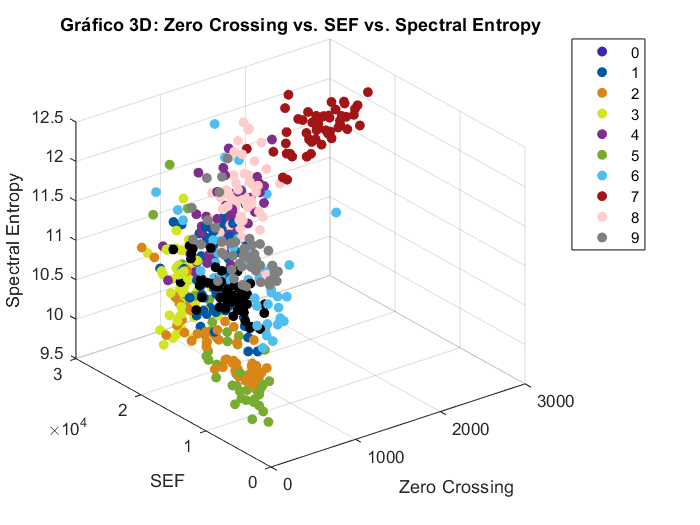


% Plot 3D 
figure;
scatter3(zero_crossing, SEF, spectral_entropy, [], digitos, 'filled');
xlabel('Zero Crossing');
ylabel('SEF');
zlabel('Spectral Entropy');
title('Gráfico 3D: Zero Crossing vs. SEF vs. Spectral Entropy');

% Mapeamento de cores para os digitos
unique_digitos = unique(digitos); % Obtém os digitos únicos
hold on;
l = cell(1, length(unique_digitos));
% Mapeamento de cores para os dígitos
for i = 1:length(unique_digitos)
    current_digit = unique_digitos(i);
    idx = digitos == current_digit;
    scatter3(zero_crossing(idx), SEF(idx), spectral_entropy(idx), [], custom_colors(current_digit+1, :), 'filled');
    l{i} = sprintf('%d', current_digit);
end
hold off;
legend(l);


% função para adivinhar os dígito
digitos_adivinhados = adivinhar_digitos(features_matrix);

% Calcula a acurácia
accuracy = calculateAccuracy(digitos, digitos_adivinhados);

% Exibe a acurácia
disp(['Acertos: ', num2str(accuracy), '%']);

Acertos: 58.4%


function zcr = zeroCrossingRate(signal)
    % Shift signal by one sample and compare signs with the original signal
    signalShifted = [0; signal(1:end-1)];  % Shift signal left
    zeroCrossings = signal .* signalShifted;  % Element-wise multiplication
    zcr = sum(zeroCrossings < 0);  % Count where product is negative
end
    
    % Função para ajustar a duração
function y = adjust_duration(y, Fs, desired_duration)
    current_duration = length(y) / Fs;
    if current_duration < desired_duration
        % Adicionar silêncio no final
        silence_duration = round((desired_duration - current_duration) * Fs);
        silence = zeros(silence_duration, 1);
        y = [y; silence];
    elseif current_duration > desired_duration
        % Retirar parte final
        samples_to_keep = round(desired_duration * Fs);
        y = y(1:samples_to_keep);
    end
end

% Função para remover o "silêncio" inicial
function y = remove_silence(y)
    % Encontrar o limiar de energia
    energy_threshold = 0.15 * max(abs(y));
    
    % Encontrar o índice onde a energia ultrapassa o limiar
    idx = find(abs(y) > energy_threshold, 1, 'first');
    
    % Remover o "silêncio" inicial
    y = y(idx:end);
end

% Função para normalizar a amplitude
function y = normalize_amplitude(y)
    % Normalizar para valores entre -1 e 1
    y = y / max(abs(y));
end

function digitos_adivinhados = adivinhar_digitos(features_matrix)
    % Inicializa o array para armazenar os dígitos adivinhados
    n_linhas = size(features_matrix, 2);
    digitos_adivinhados = zeros(1, n_linhas);

    % Percorre cada linha da matriz de características
    for i = 1:n_linhas
        % Extrai os valores das características para a linha i
        zero_crossing = features_matrix(1, i);
        total_power_stft = features_matrix(2, i);
        total_peaks_stft = features_matrix(3, i);
        SEF = features_matrix(4, i);
        spectral_entropy = features_matrix(5, i);
        std_dev = features_matrix(6, i);

        % Aplica condições para adivinhar o dígito
        if ((10 < total_peaks_stft)&&(450 < zero_crossing)&&(zero_crossing < 1150) && (10.5 < spectral_entropy)&& (spectral_entropy < 11.35) && (0.1 < std_dev) && (std_dev <0.16)&&(1*10000 < total_power_stft) &&(total_power_stft<4*10000)) 
            digitos_adivinhados(i) = 5;
            
        elseif ((13 < total_peaks_stft)&&(total_peaks_stft<26)&&(0.1<std_dev)&&(std_dev<0.18)&&(11.25 < spectral_entropy) && (spectral_entropy<12.4) &&(1.65*10000 < SEF) &&(SEF<2.50*10000) && (900<zero_crossing) && (zero_crossing<2000) && (2*10000 <total_power_stft)&&(total_power_stft < 11*10000))
            digitos_adivinhados(i) = 7;
            
        elseif ((total_peaks_stft<19)&&(SEF<1.7*10000)&&(0.12 < std_dev)&&(std_dev <0.18)&&(zero_crossing <750) && (2*10000 < total_power_stft < 7.5*10000)&&(spectral_entropy<10.75))
            digitos_adivinhados(i) = 4;
            
        elseif((11<total_peaks_stft)&&(total_peaks_stft<27)&&(1.65*10000<SEF)&&(SEF<2.5*10000)&&(11.5<spectral_entropy)&&(1500<zero_crossing)&&(0.09<std_dev)&&(std_dev<0.17))
            digitos_adivinhados(i) = 6;
            
        elseif((11<spectral_entropy)&&(spectral_entropy<12)&&(std_dev<0.14)&&(0.75*10000 < SEF)&&(SEF<2.35*10000)&&(total_power_stft<3.5*10000)&&(9<total_peaks_stft)&&(total_peaks_stft<23)&&(350<zero_crossing)&&(zero_crossing<1250))
            digitos_adivinhados(i) = 8;
            
        elseif((10.75<spectral_entropy)&&(spectral_entropy<11.25)&&(0.12<std_dev)&&(std_dev<0.18)&&(0.8*10000 < SEF)&&(SEF<1.65*10000)&&(12<total_peaks_stft)&&(total_peaks_stft<20)&&(zero_crossing<800))
            digitos_adivinhados(i) = 9;
            
        elseif(((10.2<spectral_entropy)&&(spectral_entropy<10.65)&&(0.13<std_dev)&&(std_dev<0.2)&&(0.5*10000 < SEF)&&(SEF<2*10000)&&(2.5*10000<total_power_stft)&&(total_power_stft<8*10000)&&(total_peaks_stft<20)&&(zero_crossing<750)))
            digitos_adivinhados(i) = 1;
        
        elseif((10.7<spectral_entropy)&&(spectral_entropy<12)&&(0.12<std_dev)&&(std_dev<0.19)&&(1.75*10000 < SEF)&&(SEF<2.25*10000)&&(5*10000<total_power_stft)&&(total_power_stft<9*10000)&&(11<total_peaks_stft)&&(total_peaks_stft<24)&&(500<zero_crossing)&&(zero_crossing<1500))
            digitos_adivinhados(i) = 3;
        
        elseif((10<spectral_entropy)&&(spectral_entropy<11.25)&&(0.14 < std_dev)&&(std_dev<0.22)&&(1.8*10000 < SEF)&&(SEF<2.35*10000)&&(3.25*10000<total_power_stft)&&(8<total_peaks_stft)&&(total_peaks_stft<19)&&(zero_crossing<750))
            digitos_adivinhados(i) = 2;
        
        elseif((10.3<spectral_entropy)&&(spectral_entropy<11.5)&&(std_dev>0.12)&&(std_dev<0.2)&&(1.5*10000 < SEF)&&(SEF<2.25*10000)&&(3.5*10000<total_power_stft)&&(total_power_stft <8*10000)&&(8 <total_peaks_stft)&&(total_peaks_stft<26)&&(500<zero_crossing)&&(zero_crossing<1250))
            digitos_adivinhados(i) = 0;
        end
    end
end

function accuracy = calculateAccuracy(real_digits, guessed_digits)
    % Verifica se os tamanhos dos vetores são iguais
    if length(real_digits) ~= length(guessed_digits)
        error('Os vetores de dígitos reais e adivinhados devem ter o mesmo tamanho.');
    end

    % Inicializa contador de acertos
    correct_count = 0;
    
    % Loop para percorrer cada dígito
    for i = 1:length(real_digits)
        % Verifica se os dígitos correspondem
        if real_digits(i) == guessed_digits(i)
            correct_count = correct_count + 1; % Incrementa o contador de acertos
        end
    end
    
    % Calcula a porcentagem de acertos
    accuracy = (correct_count / length(real_digits)) * 100;
end